clc; clear all; close all;
syms Vi mu a rp
a=384000

a = 384000

rp=6700

rp = 6700

Vi=2.94

Vi = 2.9400

mu=3.986*10^5

mu = 398600

 VDir=(((Vi.^2)+((2.*mu)/a))^0.5)-(mu/a)^0.5

VDir = 2.2553

 VOlb1=((mu/a)^0.5)-(((2.*mu)/a)-((2.*mu)/(a+rp)))^0.5

VOlb1 = 0.8301

 VOlb2=(((Vi.^2)+((2.*mu)/rp))^0.5)-(((2.*mu)/rp)-((2.*mu)/(a+rp)))^0.5

VOlb2 = 0.4832

VOlb=VOlb1+VOlb2

VOlb = 1.3133

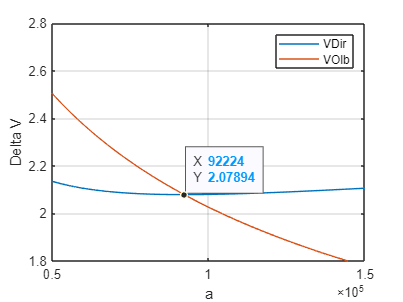

a=[(10000:200000)];
for i=1:length(a)
 VDir(i)=(((Vi.^2)+((2.*mu)/a(i)))^0.5)-(mu/a(i))^0.5;
 VOlb1(i)=((mu/a(i))^0.5)-(((2.*mu)/a(i))-((2.*mu)/(a(i)+rp)))^0.5;
 VOlb2(i)=(((Vi.^2)+((2.*mu)/rp))^0.5)-(((2.*mu)/rp)-((2.*mu)/(a(i)+rp)))^0.5;
% plot(VDir,a)
VOlb(i)=VOlb1(i)+VOlb2(i);

end 
plot(a,VDir,a,VOlb)
grid on

legend({'VDir','VOlb'})

xlim([50000 150000])
ylim([1.8 2.8])
ax = gca;
chart = ax.Children(1);
datatip(chart,92230,2.07889);

xlabel('a')
ylabel('Delta V')